# 创建深度学习网络架构

该脚本可创建具有以下属性的深度学习网络:

运行脚本以在工作区变量 `lgraph` 中创建层。

要了解详细信息，请参阅 [从深度网络设计器生成 MATLAB 代码](matlab:helpview('deeplearning','generate_matlab_code'))。

由 MATLAB 于 2023-11-22 20:37:36 自动生成

## 创建层次图

创建层次图变量以包含网络层。

lgraph = layerGraph();

## 添加层分支

将网络分支添加到层次图中。每个分支均为一个线性层组。

tempLayers = [
    imageInputLayer([227 227 3],"Name","imageinput")
    convolution2dLayer([7 7],64,"Name","conv_1","Padding","same","Stride",[2 2])
    batchNormalizationLayer("Name","batchnorm_1")
    reluLayer("Name","relu_1")
    maxPooling2dLayer([3 3],"Name","maxpool","Stride",[2 2])
    convolution2dLayer([3 3],64,"Name","conv_2","Padding","same")
    batchNormalizationLayer("Name","batchnorm_2")
    reluLayer("Name","relu_2")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],64,"Name","conv_7_1","Padding","same")
    reluLayer("Name","relu_7_1")
    convolution2dLayer([3 3],64,"Name","conv_7_2","Padding","same","Stride",[2 2])
    reluLayer("Name","relu_7_2")
    convolution2dLayer([1 1],128,"Name","conv_7","Padding","same")
    batchNormalizationLayer("Name","batchnorm_7")
    reluLayer("Name","relu_7")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = convolution2dLayer([1 1],128,"Name","conv","Padding","same","Stride",[2 2]);
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    additionLayer(2,"Name","addition_1")
    convolution2dLayer([3 3],128,"Name","conv_3","Padding","same")
    batchNormalizationLayer("Name","batchnorm_3")
    reluLayer("Name","relu_3")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([3 3],128,"Name","conv_4","Padding","same")
    batchNormalizationLayer("Name","batchnorm_4")
    reluLayer("Name","relu_4")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    additionLayer(2,"Name","addition")
    convolution2dLayer([3 3],128,"Name","conv_5","Padding","same")
    batchNormalizationLayer("Name","batchnorm_5")
    reluLayer("Name","relu_5")
    convolution2dLayer([3 3],128,"Name","conv_6","Padding","same")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    batchNormalizationLayer("Name","batchnorm_6")
    reluLayer("Name","relu_6")
    convolution2dLayer([3 3],128,"Name","conv_7_3","Padding","same")
    batchNormalizationLayer("Name","batchnorm_7_1")
    reluLayer("Name","relu_7_3")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    additionLayer(2,"Name","addition_1_1")
    convolution2dLayer([3 3],128,"Name","conv_11","Padding","same")
    batchNormalizationLayer("Name","batchnorm_11")
    reluLayer("Name","relu_11")
    averagePooling2dLayer([5 5],"Name","avgpool2d")
    fullyConnectedLayer(1024,"Name","fc_1")
    reluLayer("Name","relu6")
    dropoutLayer(0.5,"Name","drop6")
    fullyConnectedLayer(1024,"Name","fc_2")
    reluLayer("Name","relu7")
    dropoutLayer(0.5,"Name","drop7")
    fullyConnectedLayer(10,"Name","fc")
    softmaxLayer("Name","softmax")
    classificationLayer("Name","classoutput")];
lgraph = addLayers(lgraph,tempLayers);

% 清理辅助变量
clear tempLayers;

## 连接层分支

连接网络的所有分支以创建网络图。

lgraph = connectLayers(lgraph,"relu_2","conv_7_1");
lgraph = connectLayers(lgraph,"relu_2","conv");
lgraph = connectLayers(lgraph,"relu_7","addition_1/in2");
lgraph = connectLayers(lgraph,"conv","addition_1/in1");
lgraph = connectLayers(lgraph,"relu_3","conv_4");
lgraph = connectLayers(lgraph,"relu_3","addition/in1");
lgraph = connectLayers(lgraph,"relu_4","addition/in2");
lgraph = connectLayers(lgraph,"conv_6","batchnorm_6");
lgraph = connectLayers(lgraph,"conv_6","addition_1_1/in1");
lgraph = connectLayers(lgraph,"relu_7_3","addition_1_1/in2");

## 绘制层

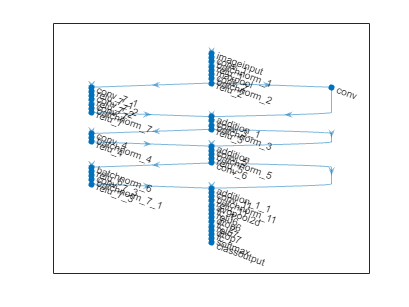

plot(lgraph);